# Controle de velocidade angular em motor DC

Alunos: Daniel Botelho, Mateus Teixeira, Samuel Alvarenga, Whilker Silva

Discilplina: GAT124 - Controle Digitais

## Identificação do sistema

### Importa os dados coletados do motor

close all; clear; clc;

% Lê os dados do arquivo Excel
file = readtable('dados.xlsx');

idf.t = file.tempo;              % Vetor de tempo (em segundos)
idf.u = file.entrada/255;        % Sinal de entrada (duty cycle entre 0 e 1)
idf.y = file.saida/340*60/0.01;  % Sinal de saída convertido para RPM

% Define o intervalo de amostragem (10 milissegundos)
Ts = 0.01;

### Filtragem dos dados

fy = 10; % Tamanho da janela do filtro de média móvel para a saída
fu = 5;  % Tamanho da janela do filtro de média móvel para a entrada

idf.uf = movmean(idf.u,fu); % Filtra a entrada usando média móvel com janela fu
idf.yf = movmean(idf.y,fy); % Filtra a saída usando média móvel com janela fy

### Offset dos dados

idf_uo = 0;         % Offset entrada (referência zero)
idf_yo = idf.yf(1); % Offset definido como o primeiro valor filtrado

% Remove os offsets da entrada e da saída
idf.uo = idf.uf - idf_uo; % Entrada sem offset
idf.yo = idf.yf - idf_yo; % Saída sem offset

### Plot dos dados

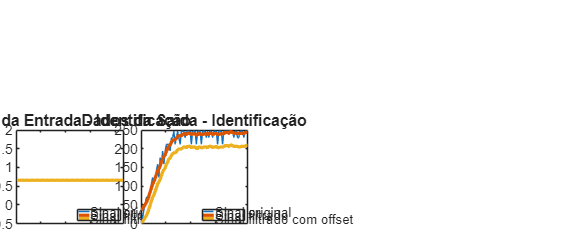

figure('Position', [100, 100, 1000, 400]);  % Cria figura com largura ajustada
tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

% --- Subplot 1 ---
nexttile
plot(idf.t, idf.u); hold on;         % sinal original de entrada
plot(idf.t, idf.uf, 'LineWidth', 2); % sinal de entrada filtrado
plot(idf.t, idf.uo, 'LineWidth', 2); % sinal de entrada filtrado e sem offset   
xlim([idf.t(1) idf.t(end)]);
title('Dados da Entrada - Identificação');                
legend('Sinal original', 'Sinal filtrado', 'Sinal filtrado com offset', ...
    'Location', 'southeast', 'FontSize', 8);   

% --- Subplot 2 ---
nexttile
plot(idf.t, idf.y); hold on;         % sinal original de saída
plot(idf.t, idf.yf, 'LineWidth', 2); % sinal de saída filtrado
plot(idf.t, idf.yo, 'LineWidth', 2); % sinal de saída filtrado e sem offset
xlim([idf.t(1) idf.t(end)]);
title('Dados da Saída - Identificação');
legend('Sinal original', 'Sinal filtrado', 'Sinal filtrado com offset', ...
    'Location', 'southeast', 'FontSize', 8);

## Obtendo função de transferência da planta

### Parametros do sistema de 1ª ordem

s = tf('s');              % Cria a variável 's' 
tamanho = length(idf.yo); % Número total de amostras 
amostras = 40;            % Número de amostras para calcular a média final
soma = 0;                

for k = tamanho-amostras+1:tamanho
    soma = soma + idf.yo(k);      % Soma os últimos valores do sinal de saída 
end

vMax = soma/amostras;             % Calcula o valor em regime permanente

% Encontra o índice em que a resposta atinge 63,2% do valor final
idx = find(idf.yo <= vMax * 0.632, 1, 'last');

k = vMax / idf.u(1); % Estima K
tau = idf.t(idx);    % Estima a constante de tempo

### Função de transferência do sistema

Gs = k / (tau*s + 1)   % Define o modelo contínuo


Gs =
 
    312.5
  ----------
  0.17 s + 1
 
Continuous-time transfer function.


Gz = c2d(Gs, Ts)       % Define o modelo discreto


Gz =
 
    17.85
  ----------
  z - 0.9429
 
Sample time: 0.01 seconds
Discrete-time transfer function.


### Plotar respostas ao degrau

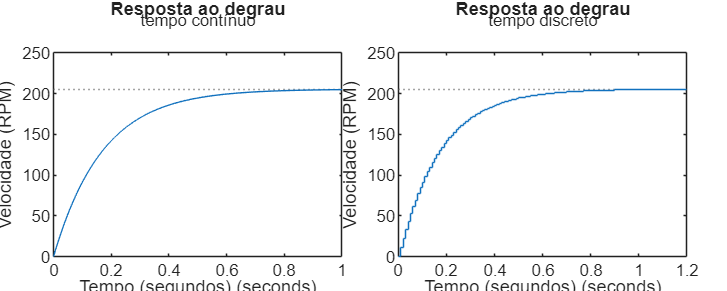

figure('Position', [100, 100, 1000, 400]);  % Cria uma figura com largura ajustada
tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact'); % Layout com dois gráficos lado a lado

% --- Subplot 1 ---
nexttile
step(Gs * 0.658);                     
title('Resposta ao degrau de 0,658');
subtitle('tempo contínuo');                     
xlabel('Tempo (segundos)');                  
ylabel('Velocidade (RPM)');                      

% --- Subplot 2 ---
nexttile
step(Gz * 0.658);                               
title('Resposta ao degrau  de 0,658')           
subtitle('tempo discreto');                      
xlabel('Tempo (segundos)')                      
ylabel('Velocidade (RPM)')                       

## Otimização

Kp_ini = 0.01; Ki_ini = 0.01; Kd_ini = 0.01;  % Valores iniciais do PID
x0 = [Kp_ini Ki_ini Kd_ini];                  % Vetor inicial para otimização

% Limites dos parâmetros do PID
Kp_max = 100; Ki_max = 100; Kd_max = 100;     % Limites superiores
Kp_min = 0;   Ki_min = 0;   Kd_min = 0;       % Limites inferiores

v_max = [Kp_max Ki_max Kd_max];               % Vetor com os limites máximos
v_min = [Kp_min Ki_min Kd_min];               % Vetor com os limites mínimos

% Especificação de desempenho desejada
Tsettle = 0.3;                                % Tempo de acomodação desejado

% Tempo de simulação e vetor de tempo
Tsim = 10;                                    % Duração total da simulação
tempo = 0:Ts:Tsim-Ts;                         % Vetor de tempo com base em Ts

% Sinal de entrada: degrau unitário
u = ones(length(tempo),1);                    % Degrau constante 

% Geração da saída de referência
tau = Tsettle/4;                        % Constante de tempo de referência
Gref = 1/(tau*s + 1);                   % Modelo de 1ª 
yref = lsim(Gref, u, tempo);            % Resposta da referência ao degrau

% Configuração e execução da otimização (fmincon)
options = optimset('Display','iter','MaxFunEvals',500);   % Opções do otimizador

[p,fval] = fmincon(@controle.funcao_custo, x0, [], [], [], [], v_min, v_max, [], options, yref, Ts, Tsim, Gz); % Otimização dos ganhos PID

%% Ganhos PID otimizados
Kp = p(1)                                     % Ganho proporcional

Kp = 0.0066

Ki = p(2)                                     % Ganho integral

Ki = 0.0399

Kd = p(3)                                     % Ganho derivativo

Kd = 3.0852e-09

## Controlador Digital PID

### Resposta do sistema em malha fechada

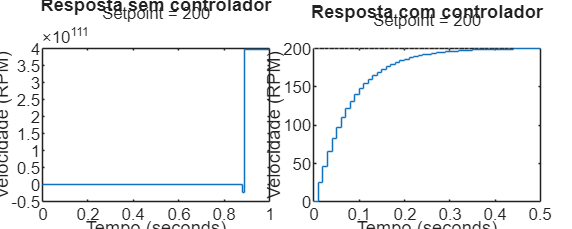

% Define o controlador PID discreto com ganhos otimizados
Gc = pid(Kp, Ki, Kd, 0, Ts, 'IFormula', 'BackwardEuler');  

%% Modelos discretos em malha fechada
Gmf1 = feedback(Gz, 1);        % Sistema em malha fechada sem controlador
Gmf2 = feedback(Gz * Gc, 1);   % Sistema em malha fechada com controlador

setpoint = 200;                % Valor desejado para a saída em PRM (referência)

figure('Position', [100, 100, 1000, 400]);  % Cria figura com tamanho ajustado
tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact'); 

% --- Subplot 1 ---
nexttile
step(Gmf1 * setpoint);                     
title('Resposta sem controlador')        
subtitle('Setpoint = 200');               
xlabel('Tempo')                          
ylabel('Velocidade (RPM)')               

% --- Subplot 2 ---
nexttile
step(Gmf2 * setpoint);                     
title('Resposta com controlador')         
subtitle('Setpoint = 200');                
xlabel('Tempo')                            
ylabel('Velocidade (RPM)')               

### Equação de Diferenças

time = 2/Ts;             % Define o número de iterações para simular 
r = ones(1, time)*200;       % Vetor de referência: degrau unitário

y1 = step(Gmf1*200, 2);      % Resposta ao degrau do sistema sem controlador
y2 = step(Gmf2*200, 2);      % Resposta ao degrau do sistema com controlador

% Laço para simular o comportamento do sistema com e sem controlador
for k = 1:time
    switch k
        case 1
            y1(k) = 0;   % Inicializa a saída da planta sem controlador
            y2(k) = 0;   % Inicializa a saída da planta com controlador
            e(k) = r(k) - y2(k);   % Calcula o erro entre referência e saída
            % Sinal de controle com PID discreto (Euler backward)
            u(k) = (Kp + Ki * Ts + Kd / Ts) * e(k); 

        case 2
            % Modelo da planta sem controlador (malha fechada)
            y1(k) = 17.85 * r(k-1) - 16.91 * y1(k-1);  
            % Modelo da planta com controlador
            y2(k) = 0.9429 * y2(k-1) + 17.85 * u(k-1);  
            e(k) = r(k) - y2(k);   % Calcula o erro atual
            % PID discreto: aproximação da derivada com 2 pontos
            u(k) = u(k-1) + Kp * e(k) - Kp * e(k-1) + ...
                   Ki * Ts * e(k) + ...
                   (Kd / Ts) * (e(k) - 2 * e(k-1)); 

        otherwise
            % Modelo da planta sem controlador (malha fechada)
            y1(k) = 17.85 * r(k-1) - 16.91 * y1(k-1);  
            % Modelo da planta com controlador
            y2(k) = 0.9429 * y2(k-1) + 17.85 * u(k-1);  
            e(k) = r(k) - y2(k);   % Calcula o erro atual
            % PID discreto completo: inclui termo derivativo de 3 pontos (segunda ordem)
            u(k) = u(k-1) + Kp * e(k) - Kp * e(k-1) + ...
                   Ki * Ts * e(k) + ...
                   (Kd / Ts) * (e(k) - 2 * e(k-1) + e(k-2));
    end
end

### Plot dos gráficos

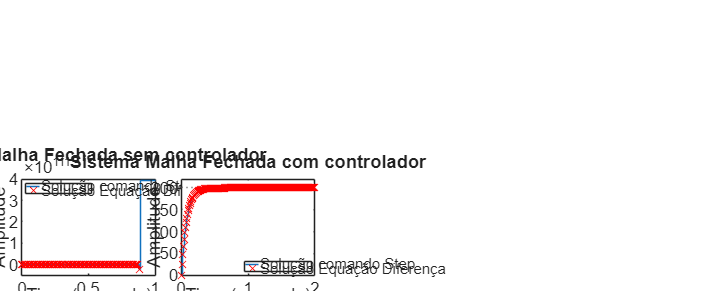

figure('Position', [100, 100, 1000, 400]);  % Cria figura com tamanho ajustado
tiledlayout(1,2, 'TileSpacing', 'compact', 'Padding', 'compact'); 

% --- Subplot 1 ---
nexttile
step(Gmf1*200); hold on; 
stairs([0:(time)]*Ts,y1,'rx');
title("Sistema Malha Fechada sem controlador");
legend('Solução comando Step', 'Solução Equação Diferença',    'Location', 'northwest' );

% --- Subplot 2 ---
nexttile
step(Gmf2*200,2); hold on; 
stairs([0:(time)]*Ts,y2,'rx');
title("Sistema Malha Fechada com controlador");
legend('Solução comando Step', 'Solução Equação Diferença',     'Location', 'southeast' );